Tmax=15;
dir '*.txt'

data.txt  



fileID = fopen('data.txt','r');
% txt = fscanf(fileID,'%s\n')
line = fgetl(fileID);
line = fgetl(fileID);
dT= str2num(line)

dT = 0.2000

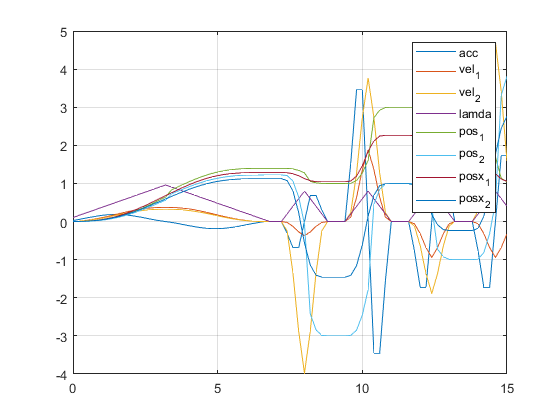

for t= 1:5
line = fgetl(fileID);
end
data = zeros(Tmax/dT+1, 11);
formatSpec = '%d, wait:%d, coll:%d, acc:%f, vel_1:%f, vel_2:%f, lamda:%f, pos_1:%f,  pos_2:%f, posx_1:%f, posx_2:%f \n';
for t= 1:Tmax/dT+1
 line = fgetl(fileID);
 if line<0 
     break; 
 end
 data(t,:) = sscanf(line,formatSpec);
end
fclose(fileID);
T= 0:dT:Tmax;
plot(T, data(:,[4 5 6,7,8,9,10, 11]))
legend('acc', 'vel_1', 'vel_2', 'lamda', 'pos_1', 'pos_2', 'posx_1', 'posx_2');

grid on

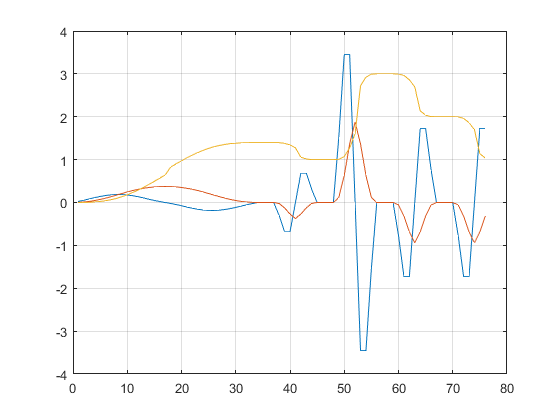


% ard  = serialport("COM3",115200);
acc= data(:,4);
vel= data(:,5);
pos= data(:,8);
%  for t= 1:100
%  line = readline(ard);
%  %data= strsplit(line,",")
%  %svel= strsplit(data(3),":")
%  %vel=str2num(svel(2))
%  [acc(t), vel(t), pos(t)]  = getData(line);
% end

plot(acc);
hold on
grid on
plot(vel);
plot(pos);
hold off

% clear ard


function [acc, vel, pos]  = getData(line)
 data= strsplit(line,",");
 sacc= strsplit(data(2),":");
  acc=str2num(sacc(2));
 svel= strsplit(data(3),":");
 vel=str2num(svel(2));
  spos= strsplit(data(6),":");
 pos=str2num(spos(2));
end